# Train DQN Agent to Balance Cart-Pole System

This example shows how to train a deep Q-learning network (DQN) agent to balance a cart-pole system modeled in MATLAB®.

For more information on DQN agents, see [Deep Q-Network Agents](docid:rl_ug#mw_101bb08b-96e7-439b-a628-afff98ca3b6f). For an example that trains a DQN agent in Simulink®, see [Train DQN Agent to Swing Up and Balance Pendulum](docid:rl_ug#mw_893a72ca-4e75-48dd-bcab-a097f50dc1ea).

## Cart-pole MATLAB Environment

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pendulum stand upright without falling over.

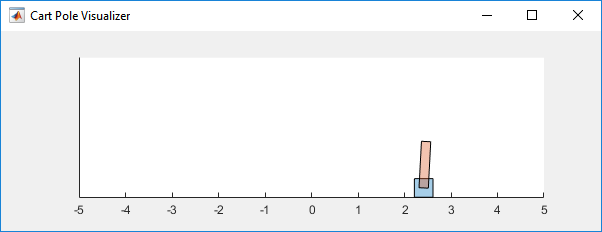

For this environment:

- The upward balanced pendulum position is `0` radians, and the downward hanging position is `pi` radians

- The pendulum starts upright with an initial angle of +/- 0.05 radians

- The force action signal from the agent to the environment is from -10 to 10 N

- The observations from the environment are the position and velocity of the cart, the pendulum angle, and its derivative

- The episode terminates if the pole is more than 12 degrees from vertical, or the cart moves more than 2.4 m from the original position

- A reward of +1 is provided for every time step that the pole remains upright. A penalty of -5 is applied when the pendulum falls.

For more information on this model, see [Load Predefined Control System Environments](docid:rl_ug#mw_537f0c6d-2ccd-454b-95fa-3ee88ece74aa).

## Create Environment Interface

Create a predefined environment interface for the pendulum.

env = rlPredefinedEnv("CartPole-Discrete")

env =   CartPoleDiscreteAction with properties:

                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5
                    State: [4×1 double]


The interface has a discrete action space where the agent can apply one of two possible force values to the cart, -10 or 10 N.

Fix the random generator seed for reproducibility.

rng(0)

## Create DQN agent

A DQN agent approximates the long-term reward given observations and actions using a critic value function representation. To create the critic, first create a deep neural network with two inputs, the state and action, and one output. For more information on creating a neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

statePath = [
    imageInputLayer([4 1 1],'Normalization','none','Name','state')
    fullyConnectedLayer(24,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(24,'Name','CriticStateFC2')];
actionPath = [
    imageInputLayer([1 1 1],'Normalization','none','Name','action')
    fullyConnectedLayer(24,'Name','CriticActionFC1')];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu')
    fullyConnectedLayer(1,'Name','output')];
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);    
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

View the critic network configuration.

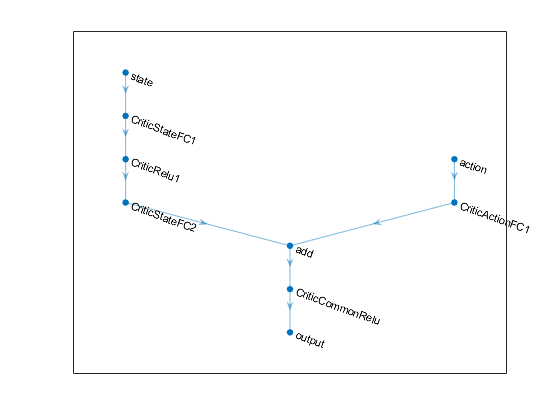

figure
plot(criticNetwork)

Specify options for the critic representation using [`rlRepresentationOptions`](docid:rl_ref#mw_45ccf57d-64f0-4822-8000-3f0f44f2572e).

criticOpts = rlRepresentationOptions('LearnRate',0.01,'GradientThreshold',1);

Create the critic representation using the specified neural network and options. You must also specify the action and observation info for the critic, which you obtain from the environment interface. For more information, see [`rlQValueRepresentation`](docid:rl_ref#mw_6e9cf856-c679-4834-97e1-1349c4a21e43).

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
critic = rlQValueRepresentation(criticNetwork,obsInfo,actInfo,'Observation',{'state'},'Action',{'action'},criticOpts);

To create the DQN agent, first specify the DQN agent options using [`rlDQNAgentOptions`](docid:rl_ref#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e).

agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN',false, ...    
    'TargetUpdateMethod',"periodic", ...
    'TargetUpdateFrequency',4, ...   
    'ExperienceBufferLength',100000, ...
    'DiscountFactor',0.99, ...
    'MiniBatchSize',256);

Then, create the DQN agent using the specified critic representation and agent options. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic,agentOpts);

## Train Agent

To train the agent, first specify the training options. For this example, use the following options:

- Run one training session containing at most 1000 episodes, with each episode lasting at most 500 time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives an moving average cumulative reward greater than 480. At this point, the agent can balance the cart-pole system in the upright position.

For more information, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 1000, ...
    'MaxStepsPerEpisode', 500, ...
    'Verbose', false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',480); 

The cart-pole system can be visualized with using the `plot` function during training or simulation.

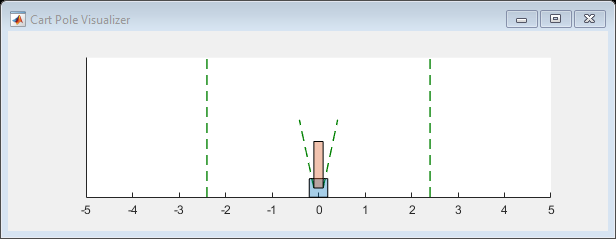

plot(env)

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This is a computationally intensive process that takes several minutes to complete. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('MATLABCartpoleDQN.mat','agent');
end

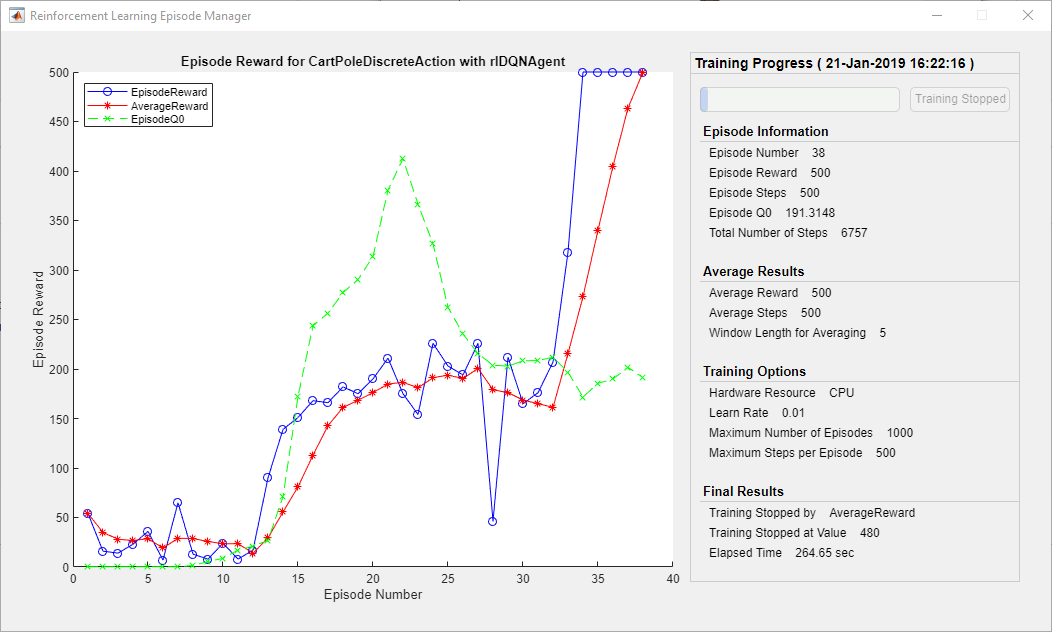

## Simulate DQN Agent

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf). The agent can balance the cart-pole even when simulation time increases to 500.

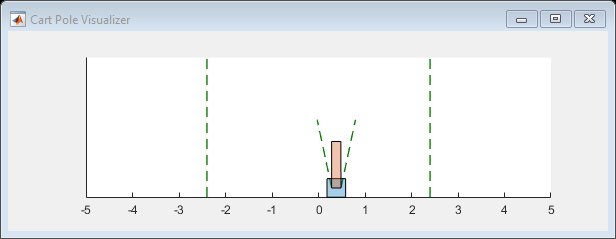

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

totalReward = sum(experience.Reward)

totalReward = 500

*Copyright 2019 The MathWorks, Inc.*